M = 64;
K = 18;
L = 13;

R = 200;
r = sqrt(3)/2*R;

theta_0 = pi/12;
max_theta = pi/18;


$$r_{12} = \frac{ | \mathbf{h}_{1}^{\mathrm{H}} \mathbf{h}_{2} | }{ \Vert \mathbf{h}_{1} \Vert_{2} \Vert \mathbf{h}_{2} \Vert_{2} }$$



$$r_{12} = \frac{1}{M} \left | \mathrm{e}^{ -\mathrm{j}(\phi_{1} - \phi_{2})} \left [ \frac{1 - \mathrm{e}^{\mathrm{j}M\pi (\sin\theta_{1} - \sin\theta_{2})}}{1 - \mathrm{e}^{\mathrm{j}\pi (\sin\theta_{1} - \sin\theta_{2})}} \right]  \right|$$



$$r_{12} = \frac{1}{M} \left | \frac{\mathrm{e}^{\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}}{\mathrm{e}^{\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}} \left [ \frac{\mathrm{e}^{\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})} - \mathrm{e}^{-\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}}{\mathrm{e}^{\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})} - \mathrm{e}^{-\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}} \right]  \right|$$



$$r_{12} = \frac{1}{M} \left | \frac{\sin \left( M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2}) \right) }{\sin \left( \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2}) \right)} \right|$$


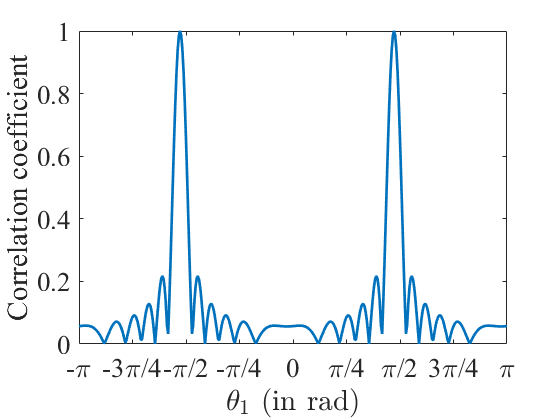

r_12 = @(theta_1,theta_2) abs(sin(M*pi/2*(sin(theta_1) - sin(theta_2) + eps))./sin(pi/2*(sin(theta_1) - sin(theta_2) + eps)))/M;

theta_1 = -pi:pi/180:pi;
theta_2 = theta_1 + max_theta;

linewidth  = 2;
fontname   = 'TImes New Roman';
fontsize   = 20;

plot(theta_1,r_12(theta_1,theta_2),'linewidth',linewidth);
% hold on;
% plot(theta_2,r_12,'linewidth',linewidth);
% hold off;

xlabel('$\theta_{1}$ (in rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([-pi -3*pi/4 -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi]);
xticklabels({'-\pi','-3\pi/4','-\pi/2','-\pi/4','0','\pi/4','\pi/2','3\pi/4','\pi'});

set(gca,'fontname',fontname,'fontsize',fontsize);

xlim([-pi pi]);
ylim([0 1]);

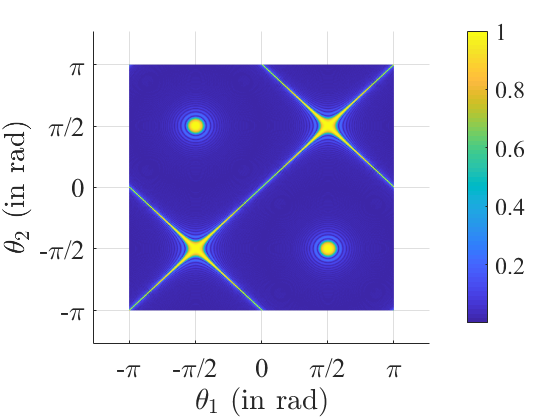

[T_1,T_2] = meshgrid(theta_1,theta_1);

surf(T_1,T_2,r_12(T_1,T_2),'edgecolor','none');
colorbar;

xlabel('$\theta_{1}$ (in rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$\theta_{2}$ (in rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
zlabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

yticks([-pi -pi/2 0 pi/2 pi]);
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

zlim([0 1]);
set(gca,'fontname',fontname,'fontsize',fontsize);


% polarplot(theta_1,r_12(theta_1,theta_2),'linewidth',linewidth);
% % hold on;
% % olarplot(theta_2,r_12,'linewidth',linewidth);
% % hold off;
% 
% rticks([0.5 1]);
% 
% thetaticks([0 45 90 135 180 225 270 315]);
% thetaticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','-3\pi/4','-\pi/2','-\pi/4'});
% 
% set(gca,'fontname',fontname,'fontsize',fontsize);
% h = figure;
% 
% filename = 'testAnimated.gif';
% 
% theta_1 = -pi:pi/18000:pi;
% 
% for d_theta = [0 1 2 3 4 5 6 7 8 9 10:5:180]*pi/180 
%     theta_2 = theta_1 + d_theta;
%            
%     polarplot(theta_1,r_12(theta_1,theta_2),'linewidth',linewidth);
%         
%     title(['$\Delta\theta = ' num2str(180*d_theta/pi) '$'],'fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%     
%     rticks([0.5 1]);
% 
%     thetaticks([0 45 90 135 180 225 270 315]);
%     thetaticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','-3\pi/4','-\pi/2','-\pi/4'});
% 
%     set(gca,'thetaaxisunit','radian','fontname',fontname,'fontsize',fontsize);
%     
%     drawnow 
%       
%     frame = getframe(h); 
%     im = frame2im(frame); 
%     [imind,cm] = rgb2ind(im,256); 
%       
%     if d_theta == 0  
%         imwrite(imind,cm,filename,'gif', 'Loopcount',inf); 
%     else 
%         imwrite(imind,cm,filename,'gif','WriteMode','append'); 
%     end 
%  end

% x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
% y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates
% 
% [x_corr,y_corr] = pol2cart(theta_1,r*r_12(theta_1,theta_2));
% 
% radius = r*sqrt(rand(K,1));
% theta  = theta_0 +  max_theta*rand(K,1);
% 
% x = radius.*cos(theta);
% y = radius.*sin(theta);
% 
% N_CIRCLE_POINTS = 100;
% 
% theta_circle  = theta_0 + max_theta*linspace(0,1,N_CIRCLE_POINTS);
% 
% x_circle = r*cos(theta_circle);
% y_circle = r*sin(theta_circle);

# Ploting Cell and Users Distribution

## Ploting Parameters

% linewidth  = 2;
% fontname   = 'TImes New Roman';
% fontsize   = 20;
% markersize = 10;

## Distribution of the Users in a Small Piece of the Cell

% plot(x_cell,y_cell,'linewidth',linewidth);
% hold on;
% plot(x_corr,y_corr,'linewidth',linewidth);
% plot([0 x_circle 0],[0 y_circle 0],'linewidth',linewidth);
% plot(0,0,'vk','linewidth',linewidth,'markersize',1.5*markersize);
% plot(x,y,'ok','linewidth',linewidth,'markersize',markersize);
% xlabel('$x$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
% ylabel('$y$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
% 
% set(gca,'fontname',fontname,'fontsize',fontsize);
% xlim([-1.25*R 1.25*R]);
% ylim([-1.25*R 1.25*R]);